# Electromagnetic Waves Project

% Clear workspace, close all figures, clear command window
clear; close all; clc;

## Parameters

Define physical parameters for Gaussian beam simulation

lambda = 4.2e-3;                % Wavelength [m]
w0     = 10e-3;                 % Beam waist [m] 
k      = 2*pi/lambda;           % Wavenumber [1/m]
zR     = pi*w0^2/lambda;        % Rayleigh range (z0) [m]
Ao     = 1;                     % Initial amplitude (normalized)

% Spatital Domain Setup
% Calculate minimum sampling step to satisfy Nyquist criterion
dx_min = sqrt(2)*pi/k;          % Minimum dx to avoid aliasing
dx = 1.1*dx_min;                % Use slightly larger step for safety

% Define grid parameters
N = 256;                        % Number of sampling points
x = (-N/2:N/2-1) * dx;
y = (-N/2:N/2-1) * dx;

% Create 2D meshgrid for spatial coordinates
[X, Y] = meshgrid(x, y);        % Makes 2d vector for x y coords
rho2 = X.^2 + Y.^2;             % Radial distance squared

% Frequency Domain Setup 
dkx = 2*pi/(N*dx);              % Setup for the coordinates of the frequency domain
dky = 2*pi/(N*dx);
kx = (-N/2:N/2-1) * dkx;
ky = (-N/2:N/2-1) * dky;
[KX, KY] = meshgrid(kx, ky);    % Makes 2d vector for frequency x y coords
KT2 = KX.^2 + KY.^2;

% Mirror parameters
f_mirror = -4*zR;               % Focal length (concave)

% Display all parameters
fprintf('\n========================================\n');

fprintf('  GROUP %d PARAMETERS\n', 12);

  GROUP 12 PARAMETERS


fprintf('========================================\n');

fprintf('Wavelength:          λ = %.2f mm\n', lambda*1e3);

Wavelength:          λ = 4.20 mm


fprintf('Beam waist:          w₀ = %.2f mm\n', w0*1e3);

Beam waist:          w₀ = 10.00 mm


fprintf('Wave number:         k = %.4f rad/mm\n', k*1e-3);

Wave number:         k = 1.4960 rad/mm


fprintf('Rayleigh range:      z₀ = %.2f mm (%.2f cm)\n', zR*1e3, (zR*1e3)/10);

Rayleigh range:      z₀ = 74.80 mm (7.48 cm)


fprintf('Focus Mirror:        f = %.2f mm (%.2f cm)\n', f_mirror*1e3, (f_mirror*1e3)/10);

Focus Mirror:        f = -299.20 mm (-29.92 cm)


fprintf('========================================\n');

## Intensity distribution at different distances

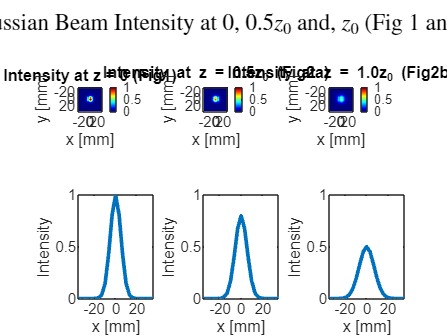

z_distances = [0,0.5*zR,zR];                                % Propagation distances: waist, half Rayleigh, full Rayleigh
for idx = 1:length(z_distances)
    Uin = Ao * exp(-rho2/w0^2);
    Uout = propagate(Uin, z_distances(idx), KT2, k);        % Propagate beam to specified distance
    I  = abs(Uout).^2;                                      % Calculate intensity from complex amplitude

     % 2D INTENSITY PLOT
    subplot(2,3,idx);
    imagesc(x*1e3, y*1e3, I);
    xlabel('x [mm]');
    ylabel('y [mm]');
    % Set appropriate title for each propagation distance
    if (idx == 1)
       title('Intensity at z = 0 (Fig1)');                                              % Beam waist
    elseif (idx ==2)
       title(sprintf('Intensity at z = %0.1fz_{0} (Fig2a)',z_distances(idx)/zR));       % Half Rayleigh
    elseif (idx ==3)
       title(sprintf('Intensity at z = %0.1fz_{0} (Fig2b)',z_distances(idx)/zR));       % Rayleigh
    end
    clim([0 1]);                                            % Set color scale limits (0 to max normalized intensity)
    colorbar;
    colormap(jet);
    shading interp;
    axis equal tight;
    xlim([-35,35]);
    ylim([-35,35]);

    % 1D CROSS-SECTION PLOT
    daspect([1 1 1]);
    subplot(2,3,idx+3);
    plot(x*1e3,I(N/2+1,:), 'LineWidth', 2);                 % Plot intensity slice along y=0
    xlabel('x [mm]');
    ylabel('Intensity');
    ylim([0 1])
    xlim([-35 35])
    % Overall title for the figure
    sgtitle('Gaussian Beam Intensity at $0$, $0.5z_{0}$ and, $z_{0}$ (Fig 1 and 2)', 'Interpreter','latex');

end

## Parabolic Mirror Reflection

Define mirror phase transformation 

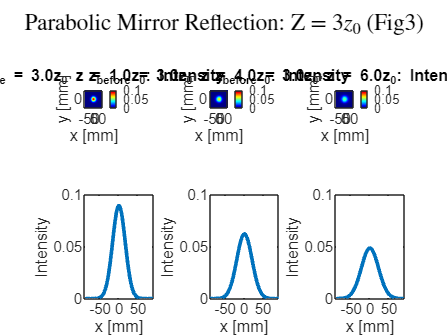

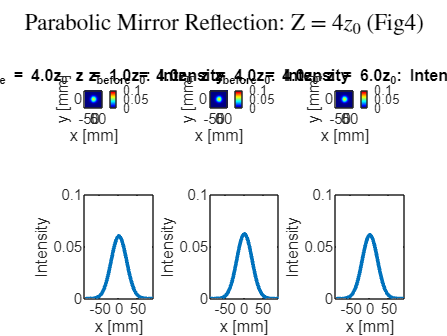

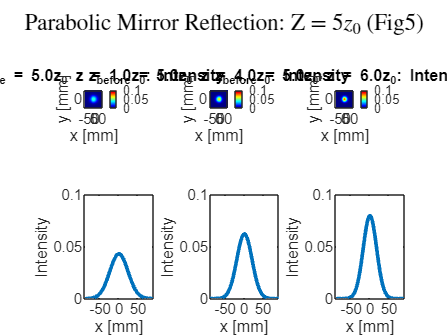

M = exp(-1i*k*(X.^2+Y.^2)/(2*f_mirror));                    % Parabolic mirror transfer function
% Define propagation distances to mirror (incident beam distances)
z_distances = [3*zR,4*zR,5*zR];
for idx = 1:length(z_distances)
    figure();                                               % Create new figure for each reflection scenario
    Uin = Ao * exp(-rho2/w0^2);
    Uout = propagate(Uin, z_distances(idx), KT2, k);
    % Apply mirror reflection (phase transformation)
    Ureflect = Uout .* M;

    % Define post-reflection propagation distances
    z_reflection_distances = [zR,4*zR,6*zR];

    % Analyze beam evolution after reflection
    for jdx = 1:length(z_reflection_distances)
        Uout2 = propagate(Ureflect, z_reflection_distances(jdx), KT2, k);
        I2  = abs(Uout2).^2;

        % 2D POST-REFLECTION INTENSITY PLOT 
        subplot(2,3,jdx);
        imagesc(x*1e3, y*1e3, I2);
        xlabel('x [mm]');
        ylabel('y [mm]');
        title(sprintf('z_{before} = %.1fz_0 z = %.1fz_0: Intensity',z_distances(idx)/zR,z_reflection_distances(jdx)/zR));
        clim([0 0.1]);  
        colorbar;
        colormap(jet);
        shading interp;
        axis equal tight;
        xlim([-90,90]);
        ylim([-90,90]);

        % 1D POST-REFLECTION CROSS-SECTION PLOT
        daspect([1 1 1]);
        subplot(2,3,jdx+3);
        plot(x*1e3,I2(N/2+1,:), 'LineWidth', 2);
        xlabel('x [mm]');
        ylabel('Intensity');
        ylim([0 0.1])
        xlim([-90 90])

    end

    % Add overall figure title
    sgtitle(sprintf('Parabolic Mirror Reflection: Z = $%0.0f z_{0}$ (Fig%0d)', z_distances(idx)/zR, idx+2), 'Interpreter','latex');

end

## Propagation Function

function Uout = propagate(Uin, propagation_length, KT2, k)
    % STEP 1: Transform to spatial frequency domain
    % ifftshift centers the frequency spectrum, fft2 computes 2D FFT
    U2 = fftshift(fft2(ifftshift(Uin)));

    % STEP 2: Calculate propagation phase factor
    % Paraxial approximation: kz ≈ k - (kx^2 + ky^2)/(2k)
    kz = k - KT2/(2*k);     

    % Apply propagation phase shift in frequency domain
    U3 = U2 .* exp(-1i*kz*propagation_length);

    % STEP 3: Transform back to spatial domain
    % fftshift recenters, ifft2 computes inverse 2D FFT
    Uout = ifftshift(ifft2(fftshift(U3)));
end